## Análisis cinemático

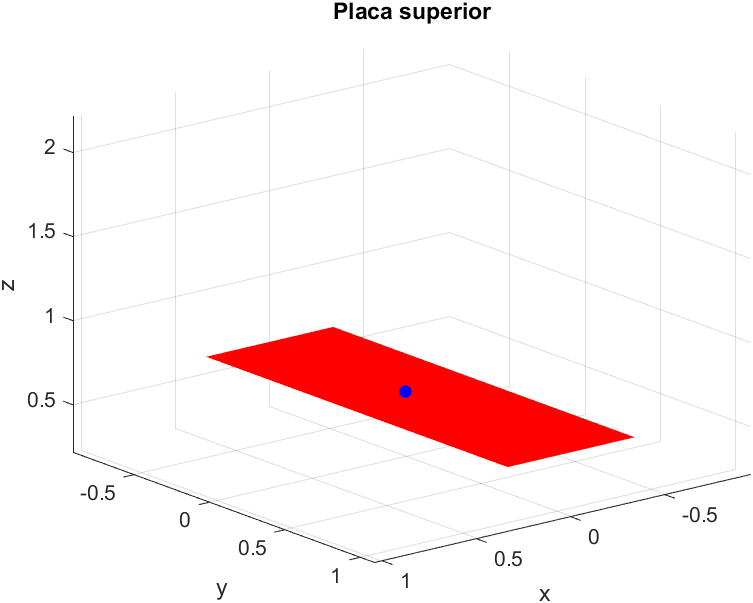

b=2.365;
h=0.57;

syms Fbeta(t) Ftheta(t) x y z x_x(t) x_z(t)

Pi=[x y z];

### Ecuaciones generales


Wbeta(t)=[Fbeta(t) 0 0];
Wtheta(t)=[0 Ftheta_c(t) 0];
Wtotal(t)=diff(Wbeta(t)+Wtheta(t));

VelocidadPO(t)=cross(Wtotal(t),Pi);
aceleracionAngular(t)=diff(Wtotal(t));

AceleracionPO(t)=cross(aceleracionAngular(t),Pi)+cross(Wtotal(t),VelocidadPO(t));


Velocidad=formula(VelocidadPO(t)+diff([x_x(t) 0 x_z(t)]));
Vx=Velocidad(1)

$$Vx = \begin{array}{l} \left\{ \begin{array}{cl} \frac{\partial }{\partial t}x_{x}\left(t\right)+\frac{50\,\sqrt{2}\,\sqrt{3}\,z\,t^{2}}{\sqrt{\pi }} & \text{ if }t\in \left(0,\frac{\sigma_{2}}{60}\right)\\ \frac{\partial }{\partial t}x_{x}\left(t\right)+z\,\left(10\,t-\frac{\sigma_{2}}{12}\right) & \text{ if }t\in \left(\frac{\sigma_{2}}{60},\frac{\sigma_{2}}{30}\right)\\ \frac{\partial }{\partial t}x_{x}\left(t\right)-z\,\left(\sigma_{1}-30\,t+\frac{5\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{12}\right) & \text{ if }t\in \left(\frac{\sigma_{2}}{30},\frac{\sigma_{2}}{20}\right)\\ \frac{\partial }{\partial t}x_{x}\left(t\right)+\frac{\sqrt{2}\,\sqrt{3}\,z\,\sqrt{\pi }}{3} & \text{ if }t\in \left(\frac{\sigma_{2}}{20},\frac{\sigma_{2}}{10}\right)\\ \frac{\partial }{\partial t}x_{x}\left(t\right)-z\,\left(\sigma_{1}-60\,t+\frac{8\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{3}\right) & \text{ if }t\in \left(\frac{\sigma_{2}}{10},\sigma_{3}\right)\\ \frac{\partial }{\partial t}x_{x}\left(t\right)-z\,\left(10\,t-\frac{17\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{12}\right) & \text{ if }t\in \left(\sigma_{3},\sigma_{4}\right)\\ \frac{\partial }{\partial t}x_{x}\left(t\right)+z\,\left(\sigma_{1}-90\,t+\frac{27\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{4}\right) & \text{ if }t\in \left(\sigma_{4},\frac{3\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{20}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{50\,\sqrt{2}\,\sqrt{3}\,t^{2}}{\sqrt{\pi }}\\ \sigma_{2}=\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }\\ \sigma_{3}=\frac{7\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{60}\\ \sigma_{4}=\frac{2\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{15} \end{array}$$

Vy=Velocidad(2)

$$Vy = -z\,\frac{\partial }{\partial t}\mathrm{Fbeta}\left(t\right)$$

Vz=Velocidad(3)

$$Vz = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1}+\frac{\partial }{\partial t}x_{z}\left(t\right)-\frac{50\,\sqrt{2}\,\sqrt{3}\,t^{2}\,x}{\sqrt{\pi }} & \text{ if }t\in \left(0,\frac{\sigma_{3}}{60}\right)\\ \sigma_{1}+\frac{\partial }{\partial t}x_{z}\left(t\right)-x\,\left(10\,t-\frac{\sigma_{3}}{12}\right) & \text{ if }t\in \left(\frac{\sigma_{3}}{60},\frac{\sigma_{3}}{30}\right)\\ \sigma_{1}+x\,\left(\sigma_{2}-30\,t+\frac{5\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{12}\right)+\frac{\partial }{\partial t}x_{z}\left(t\right) & \text{ if }t\in \left(\frac{\sigma_{3}}{30},\frac{\sigma_{3}}{20}\right)\\ \sigma_{1}+\frac{\partial }{\partial t}x_{z}\left(t\right)-\frac{\sqrt{2}\,\sqrt{3}\,x\,\sqrt{\pi }}{3} & \text{ if }t\in \left(\frac{\sigma_{3}}{20},\frac{\sigma_{3}}{10}\right)\\ \sigma_{1}+x\,\left(\sigma_{2}-60\,t+\frac{8\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{3}\right)+\frac{\partial }{\partial t}x_{z}\left(t\right) & \text{ if }t\in \left(\frac{\sigma_{3}}{10},\sigma_{4}\right)\\ \sigma_{1}+\frac{\partial }{\partial t}x_{z}\left(t\right)+x\,\left(10\,t-\frac{17\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{12}\right) & \text{ if }t\in \left(\sigma_{4},\sigma_{5}\right)\\ \sigma_{1}-x\,\left(\sigma_{2}-90\,t+\frac{27\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{4}\right)+\frac{\partial }{\partial t}x_{z}\left(t\right) & \text{ if }t\in \left(\sigma_{5},\frac{3\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{20}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=y\,\frac{\partial }{\partial t}\mathrm{Fbeta}\left(t\right)\\ \sigma_{2}=\frac{50\,\sqrt{2}\,\sqrt{3}\,t^{2}}{\sqrt{\pi }}\\ \sigma_{3}=\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }\\ \sigma_{4}=\frac{7\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{60}\\ \sigma_{5}=\frac{2\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{15} \end{array}$$


Aceleracion=formula(AceleracionPO(t)+diff(diff([x_x(t) 0 x_z(t)])))

Ax=Aceleracion(1)

Ay=Aceleracion(2)

Az=Aceleracion(3)

$$Az = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1}-\sigma_{2}+\sigma_{3}-\frac{15000\,t^{4}\,z}{\pi }-\frac{100\,\sqrt{2}\,\sqrt{3}\,t\,x}{\sqrt{\pi }} & \text{ if }t\in \left(0,\frac{\sigma_{5}}{60}\right)\\ \sigma_{1}-z\,{\left(10\,t-\frac{\sigma_{5}}{12}\right)}^{2}-\sigma_{2}-10\,x+\sigma_{3} & \text{ if }t\in \left(\frac{\sigma_{5}}{60},\frac{\sigma_{5}}{30}\right)\\ x\,\left(\sigma_{6}-30\right)-\sigma_{2}-z\,{\left(\sigma_{4}-30\,t+\frac{5\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{12}\right)}^{2}+\sigma_{1}+\sigma_{3} & \text{ if }t\in \left(\frac{\sigma_{5}}{30},\frac{\sigma_{5}}{20}\right)\\ \sigma_{1}-\sigma_{2}-\frac{2\,\pi \,z}{3}+\sigma_{3} & \text{ if }t\in \left(\frac{\sigma_{5}}{20},\frac{\sigma_{5}}{10}\right)\\ x\,\left(\sigma_{6}-60\right)-\sigma_{2}-z\,{\left(\sigma_{4}-60\,t+\frac{8\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{3}\right)}^{2}+\sigma_{1}+\sigma_{3} & \text{ if }t\in \left(\frac{\sigma_{5}}{10},\sigma_{7}\right)\\ 10\,x-z\,{\left(10\,t-\frac{17\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{12}\right)}^{2}-\sigma_{2}+\sigma_{1}+\sigma_{3} & \text{ if }t\in \left(\sigma_{7},\sigma_{8}\right)\\ \sigma_{1}-\sigma_{2}-z\,{\left(\sigma_{4}-90\,t+\frac{27\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{4}\right)}^{2}-x\,\left(\sigma_{6}-90\right)+\sigma_{3} & \text{ if }t\in \left(\sigma_{8},\frac{3\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{20}\right) \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=y\,\frac{\partial^{2}}{\partial t^{2}}\mathrm{Fbeta}\left(t\right)\\ \sigma_{2}=z\,{\left(\frac{\partial }{\partial t}\mathrm{Fbeta}\left(t\right)\right)}^{2}\\ \sigma_{3}=\frac{\partial^{2}}{\partial t^{2}}x_{z}\left(t\right)\\ \sigma_{4}=\frac{50\,\sqrt{2}\,\sqrt{3}\,t^{2}}{\sqrt{\pi }}\\ \sigma_{5}=\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }\\ \sigma_{6}=\frac{100\,\sqrt{2}\,\sqrt{3}\,t}{\sqrt{\pi }}\\ \sigma_{7}=\frac{7\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{60}\\ \sigma_{8}=\frac{2\,\sqrt{2}\,\sqrt{3}\,\sqrt{\pi }}{15} \end{array}$$


clearvars -except tMax_a tMax_c tMax_b Fz_arfada Fbeta Ftheta_c theta1 P_z C_x C_y D_x D_y D_z L_m L_b theta_C beta Z_arfada
